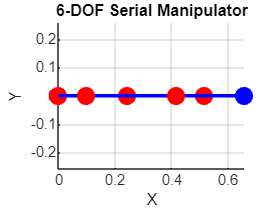

syms thetadot1 thetadot2 thetadot3 thetadot4 thetadot5 thetadot6 
n=6;
% determine x,y and z
X = zeros(3, n); X(1,:)=ones(1,n);
Y = zeros(3, n); Y(2,:)=ones(1,n);
Z = zeros(3, n); Z(3,:)=ones(1,n);
% links and skrew matrix
Lb1=.2*Z(:,1); L12=.2*Z(:,2); L23=.2*X(:,2); L34=.2*Z(:,3); L45=.2*X(:,4); L56=.2*X(:,5); L6t=.2*Z(:,6);
Lb1_hat=cross([Lb1 Lb1 Lb1],eye(3));
L12_hat=cross([L12 L12 L12],eye(3));
L23_hat=cross([L23 L23 L23],eye(3));
L34_hat=cross([L34 L34 L34],eye(3));
L45_hat=cross([L45 L45 L45],eye(3));
L56_hat=cross([L56 L56 L56],eye(3));
L6t_hat=cross([L6t L6t L6t],eye(3));
I=eye(3);
% phi matrix
phi_21=[I zeros(3);-L12_hat I]; phi_32=[I zeros(3);-L23_hat I]; phi_43=[I zeros(3);-L34_hat I]; 
phi_54=[I zeros(3);-L45_hat I]; phi_65=[I zeros(3); -L6t_hat I];
phi_31 = phi_32*phi_21; phi_42 = phi_43*phi_32; phi_41 = phi_42*phi_21;
phi_53=phi_54*phi_43;   phi_52= phi_53*phi_32;  phi_51=phi_53*phi_31; 
phi_64=phi_65*phi_54;   phi_63=phi_65*phi_53;   phi_62=phi_65*phi_52;  phi_61=phi_65*phi_51;
phi_t6 = [I zeros(3); -L6t_hat I]; phi_t = [zeros(6) zeros(6) zeros(6) zeros(6) zeros(6) phi_t6]; 
phi_b1 = [I zeros(3); -Lb1_hat I]; phi_b = [phi_b1; zeros(6); zeros(6); zeros(6); zeros(6); zeros(6)];
phi = [eye(6) zeros(6) zeros(6) zeros(6) zeros(6) zeros(6);
    phi_21 eye(6) zeros(6) zeros(6) zeros(6) zeros(6);
    phi_31 phi_32 eye(6) zeros(6) zeros(6) zeros(6);
    phi_41 phi_42 phi_43 eye(6) zeros(6) zeros(6);
    phi_51 phi_52 phi_53 phi_54 eye(6) zeros(6);
    phi_61 phi_62 phi_63 phi_64 phi_65 eye(6)];

% joints type : 1 is revolute and 0 is prizmatic
joint_type= [1 1 0 1 1 1];
h1=[0; 1; 0]; h_hat1 =  cross([h1 h1 h1],eye(3));
h2=[0; 1; 0]; h_hat2 =  cross([h2 h2 h2],eye(3));
h3=[0; 1; 0]; h_hat3 =  cross([h3 h3 h3],eye(3));
h4=[0; 1; 0]; h_hat4 =  cross([h4 h4 h4],eye(3));
h5=[0; 1; 0]; h_hat5 =  cross([h5 h5 h5],eye(3));
h6=[0; 1; 0]; h_hat6 =  cross([h6 h6 h6],eye(3));
H1=[0; 1; 0; zeros(3,1)]; H2=[0; 1; 0; zeros(3,1)]; H3=[zeros(3,1); 0; 1; 0]; 
H4=[0; 1; 0; zeros(3,1)]; H5=[0; 1; 0; zeros(3,1)]; H6=[0; 1; 0; zeros(3,1)];
H = [H1 zeros(6,1) zeros(6,1) zeros(6,1) zeros(6,1) zeros(6,1); 
    zeros(6,1) H2 zeros(6,1) zeros(6,1) zeros(6,1) zeros(6,1); 
    zeros(6,1) zeros(6,1) H3 zeros(6,1) zeros(6,1) zeros(6,1); 
    zeros(6,1) zeros(6,1) zeros(6,1) H4 zeros(6,1) zeros(6,1); 
    zeros(6,1) zeros(6,1) zeros(6,1) zeros(6,1) H5 zeros(6,1); 
    zeros(6,1) zeros(6,1) zeros(6,1) zeros(6,1) zeros(6,1) H6];
% jacobian matrix
J = phi_t * phi * H;

% find thetadot
phi_tb = phi_t * phi * phi_b;

% find V

%thetadot = [thetadot1; thetadot2; thetadot3; thetadot4];
V1 = H1 .* thetadot1;
V2 = phi_21*V1+H2.*thetadot2;
V3 = phi_32*V2+H3.*thetadot3;
V4 = phi_43*V3+H4.*thetadot4;
V5 = phi_54*V4+H5.*thetadot5;
V6 = phi_65*V5+H6.*thetadot6;
V = [V1; V2; V3; V4; V5; V6];

Vt = phi_t * V;
J_inverse = pinv(J);
thetadot = J_inverse * Vt;

% rotation matrix
R1 = eye(3) + h_hat1.*sin(thetadot1)+(h_hat1)^2*(1-cos(thetadot1));
R2 = eye(3) + h_hat2.*sin(thetadot2)+(h_hat2)^2*(1-cos(thetadot2));
R3 = eye(3) + h_hat3.*sin(thetadot3)+(h_hat3)^2*(1-cos(thetadot3));
R4 = eye(3) + h_hat4.*sin(thetadot4)+(h_hat4)^2*(1-cos(thetadot4));
R5 = eye(3) + h_hat5.*sin(thetadot5)+(h_hat5)^2*(1-cos(thetadot5));
R6 = eye(3) + h_hat6.*sin(thetadot6)+(h_hat6)^2*(1-cos(thetadot6));
%-------------------------------------------------------------------------------

